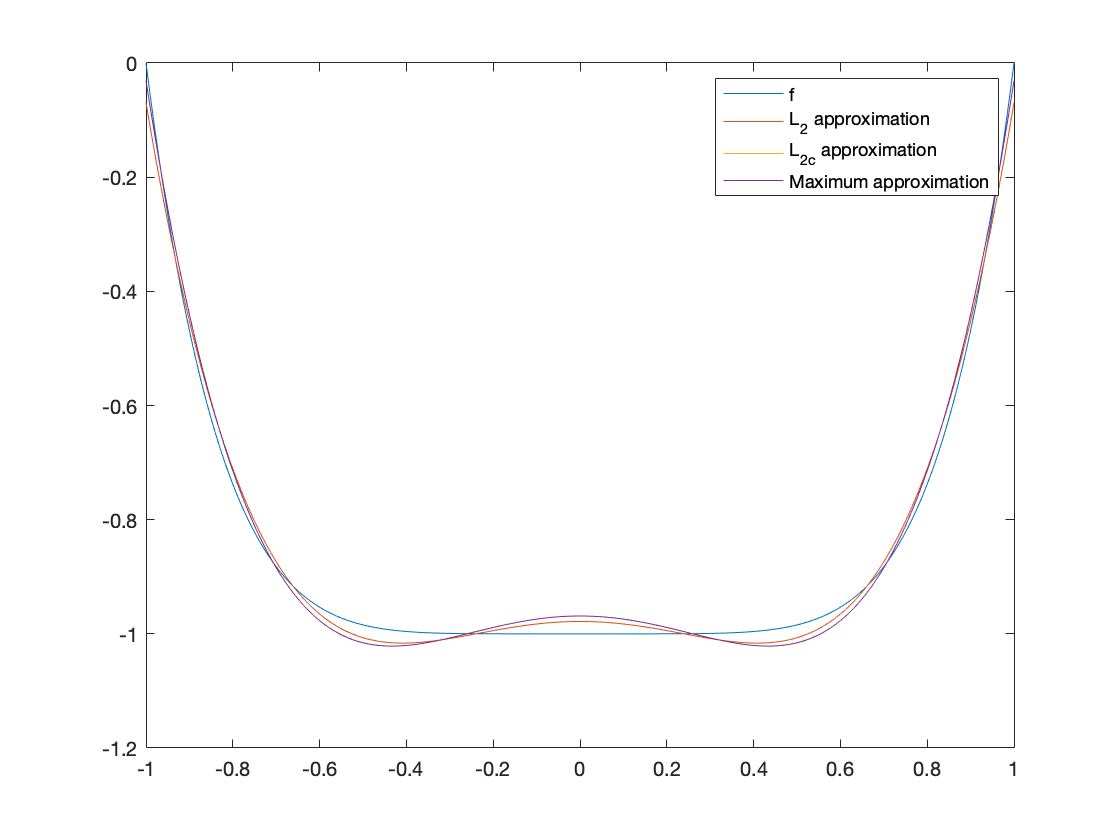

p5_hat = -(2.^(-5)).*Tscheby_poly(6);
p5_hat(1) = p5_hat(1) +1;
p5_hat(7) = p5_hat(7) -1;
figure
x = -1:0.01:1;
plot(x,f(x))
hold on
plot(x,polyval(p5,x));
plot(x,polyval(p5_tild,x));
plot(x,polyval(p5_hat,x));
legend('f','L_2 approximation','L_{2c} approximation','Maximum approximation')


res1 = max(abs(f(x) - polyval(p5_tild,x)))

res1 =    0.031250000000000


res2 = max(abs(f(x) - polyval(p5_hat,x)))

res2 =    0.031250000000000


function c = Legendre_poly(n)
if n == 0
    c = 1;
    return
end
if n == 1
    c = [1,0]';
    return
end

c0 = 1;
c1 = [1,0]';
cx = c1; 
% p_{n} = (2*n-1)/(n) x * p_{n-1} - (n-1)/(n)*p_{n-2}
for i = 2 : n
    c0 = [0;0;c0(:,1)];
    c = (2*i-1)/i * conv(cx,c1) - (i-1)/i * c0;
    c0 = c1;
    c1 = c;
end
end

function c = Tscheby_poly(n)
if n == 0
    c = 1;
    return
end
if n == 1
    c = [1,0]';
    return
end

c0 = 1;
c1 = [1,0]';
cx = c1; 
% p_{n} = 2x * p_{n-1} - p_{n-1}
for i = 2 : n
    c0 = [0;0;c0(:,1)];
    c = 2 * conv(cx,c1) - c0;
    c0 = c1;
    c1 = c;
end
end


function c = L2_BN(f,k)
d = zeros((k+1),1);
c = d;
int_fx = zeros((k+1),1);

for i = (k+1) : -1 : 1
    int_fx(i) = integral(@(x)(f(x) .* x.^(k+1 - i)),-1,1);
    d(i) = Legendre_poly(k+1-i)' * int_fx(i : end,1);
    d(i) = d(i) * (2*(k+1-i)+1)/2;
    c(i:end,1) = c(i:end,1) + d(i) * Legendre_poly(k+1-i);
end
end



function c = L2c_BN(f,k)
d = zeros((k+1),1);
c = d;
int_fx = zeros((k+1),1);

for i = (k+1) : -1 : 1
    int_fx(i) = integral(@(x)(f(x) .* x.^(k+1 - i) ./sqrt(1-x.^2)),-1,1);
    d(i) = Tscheby_poly((k+1-i))' * int_fx(i : end,1);
    if i == (k+1)
        d(i) = d(i) / pi;
    else 
        d(i) = d(i)/(pi/2);
    end
    c(i:end,1) = c(i:end,1) + d(i) * Tscheby_poly(k+1-i);
    
end
end